# **Procesarea imaginilor - Netezirea imaginii (smoothing)**

## **Notiuni generale**

- **atenuarea/estomparea** zgomotelor (pixeli paraziți) sau a fluctuațiilor mici => pentru filtrare

- ** laboratorul urmator vom discuta despre operatorii gradient => **detecția muchiilor/liniilor**

- atenuarea => prin **mediere **(dintr-o vecinătate *O*)

- **zgomote: **impuls(*salt and peper*), gaussian, poisson

###     a. Medierea 

- se realizează prin aplicarea unei **măști de convoluție *****h***

- tipuri de **măști: **

% mediere intr-o vecinătate locală 3x3
h = 1/9 * [ 1 1 1; ...
            1 1 1; ...
            1 1 1]

% mediere cu accentuarea pixelului central 
h = 1/10 * [ 1 1 1; ...
             1 2 1; ...
             1 1 1]

% mediere cu accentuarea pixelilor tetraconectați 
% sau filtru gaussian
h = 1/16 * [ 1 2 1; ...
             2 4 2; ...
             1 2 1]

- ***=> *****cum se realizeaza operația de convoluție??**

###     b. Medierea cu limitarea datelor

- se încearcă evitarea umbririi muchiilor făcând medierea doar pentru pixelii dintr-un anumit interval / care satisfac un anumit criteriu

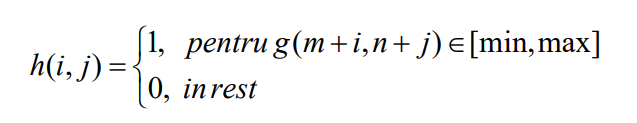

### **    c**. Filtre spațiale

    - **Liniare**: combinație liniară a pixelilor din imaginea inițială prin intermediul măștii de filtrare

    **- Neliniare**: diferite operații statistice (min-max, median)

## Matlab functions

### imfilter

- **filtrarea** imaginii și **modificarea dimensiunii **acesteia prin intermediul unei **metode de interpolare **

- **see *****help***

### **conv2**

- ** convoluție bidimensională**

- **see *****help***

### ** imnoise**

- **adaugă zgomot **unei imagini

- **see ***** help*** 

### ordfilt2 

- generare **filtru neliniar statistic**

- **see *****help***

### **medfilt2**

- **filtru median**

- **see *****help***

### **fspecial **

- **generare de filtru după specificații**

- **see *****help***

## Exemplul

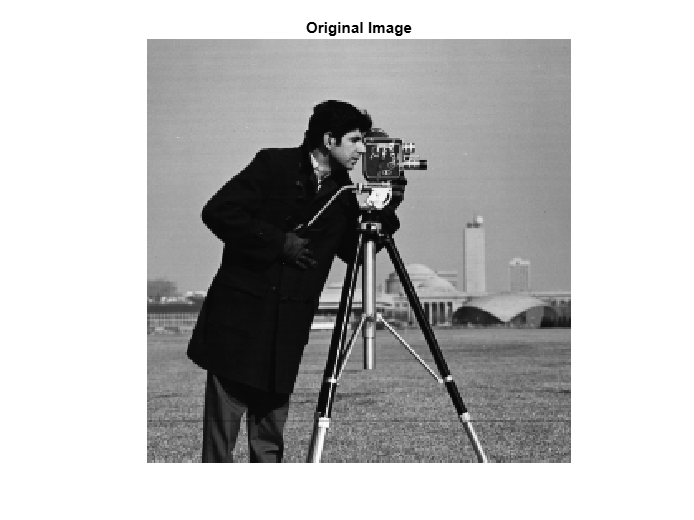

I = imread('cameraman.tif');
figure()
% show original image
figure()
imshow(I);
title('Original Image');

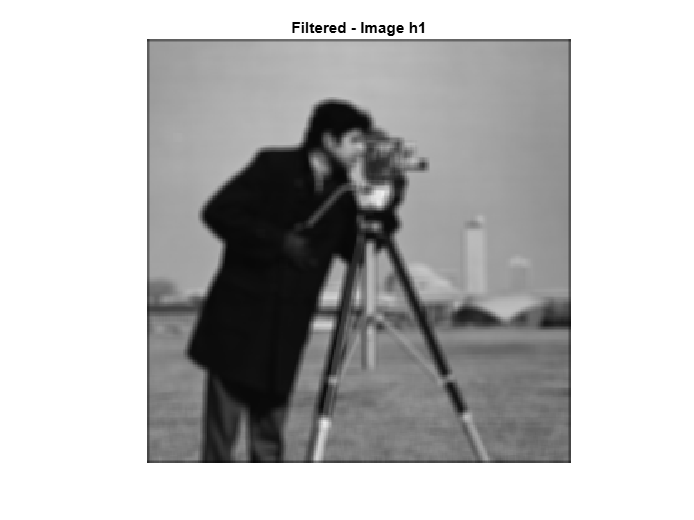


% create a convolution mask of 5x5
h = ones(5,5) / 25;
% apply the mask to the image
I1 = imfilter(I,h);
% show filtered image
figure()
imshow(I1); 
title('Filtered - Image h1');

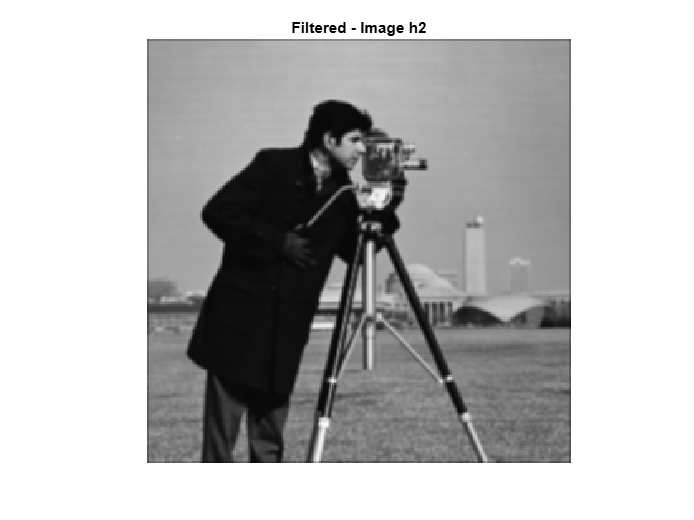

% create a convolution mask - gaussian
h2 = [1 2 1; 2 4 2; 1 2 1];
h2= h2 / sum(h2(:));
% apply the mask to the image
I2= imfilter(I,h2);
% show filtered image
figure()
imshow(I2);
title('Filtered - Image h2');

## Exercitiul 1

- **Citiți** imaginea **coins.png**

- **Aplicați** cele **3 filtre liniare de mediere **folosind funcția ***imfilter***

- **Afișați rezultatele **folsind ***subplot***

## Exercitiul 2

- **Citiți** imaginea **coins.png**

- **Aplicați diferite tipuri de zgomot (***salt and peper, poisson, gaissian***) pe aceasta imagine **folosind ***imnoise***

- **Aplicați** cele **3 filtre liniare de mediere **de la exercițiul anterior folosind funcția ***imfilter***

- **Afișați rezultatele **folsind ***subplot***

- **Interpretați rezultatele**

## Exercitiul 3

- **Reluați ex 2, de data aceasta doar cu imaginea afectata de zgomot *****salt and peper***

- **Aplicați un filtru de mediere folsind funcția *****medfilt2***

- **Suplimentar, aplicați și o ajustare a imaginii folosind funcția *****imadjust***

- **Interpretați rezultatele comparativ cu ex 2**

## Exercitiul 4

- **Reluați ex 2, de data aceasta doar cu imaginea afectata de zgomot poisson**

- **Aplicați un filtru *****liniar de medie geometrică***** și unul *****neliniar de minim***

- **Suplimentar, aplicați și o ajustare a imaginii folosind funcția *****imadjust***

## Exercitiul 5

- **Citiți** imagile puse la dispoziție în laboratorul de astăzi: ***L5_image_01.png ***și ***L5_image_02.tif***

- **Aplicați o serie de filtre și ajustări ale imaginii la alegere **

- **Aceste filtre se pot aplica fie singular, fie combinate**

- **Scopul este sa ajungeți la o reprezentare cat mai clara a imaginilor, estompand zgomotul**